# ex2.2

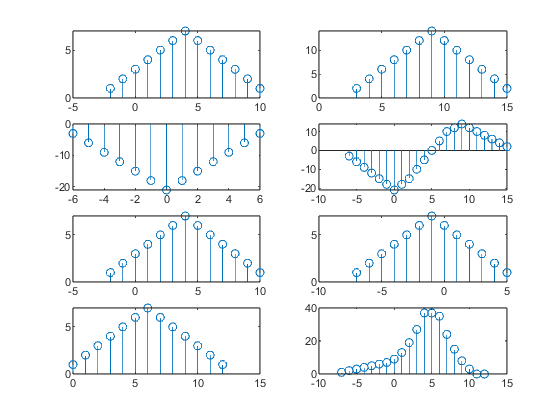

clear;clf
n=-2:10;
x=[1:7,6:-1:1];
subplot(4,2,1);stem(n,x);
[x11,n11]=sigshift(x,n,5);
subplot(4,2,2);stem(n11,2*x11);
[x12,n12]=sigshift(x,n,-4);
subplot(4,2,3);stem(n12,-3*x12);
[x1,n1] = sigadd(2*x11,n11,-3*x12,n12);
subplot(4,2,4);stem(n1,x1);
subplot(4,2,5);stem(n,x);
[x21,n21]=sigfold(x,n);
[x21,n21]=sigshift(x21,n21,3);
subplot(4,2,6);stem(n21,x21);
[x22,n22]=sigshift(x,n,2);
subplot(4,2,7);stem(n22,x22);
[x22,n22]=sigmult(x,n,x22,n22);
[x2,n2]=sigadd(x21,n21,x22,n22);
subplot(4,2,8);stem(n2,x2);

## ex2.3

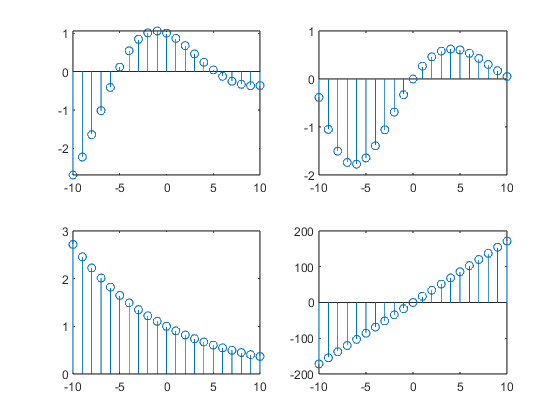

clear;clf;
n=[-10:1:10];
alpha=-0.1+0.3j;
x=exp(alpha*n);
subplot(2,2,1);stem(n,real(x));
subplot(2,2,2);stem(n,imag(x));
subplot(2,2,3);stem(n,abs(x));
subplot(2,2,4);stem(n,(180/pi)*angle(x));

## ex2.4

clear;clf;
n=[0:10];
x=stepseq(0,0,10)-stepseq(10,0,10);
[xe,xo,m]=evenodd(x,n);
subplot(2,2,1);stem(n,x);axis([-10,10,0,1.2])
subplot(2,2,2);stem(m,xe);
subplot(2,2,3);stem(m,xo);

## ex2.9

clear;clf;
x=[3,11,7,0,-1,4,2]

x =      3    11     7     0    -1     4     2


nx=[-3:3]

nx =     -3    -2    -1     0     1     2     3


subplot(2,2,1);stem(nx,x);
h=[2,3,0,-5,2,1];
nh=[-1:4]

nh =     -1     0     1     2     3     4


subplot(2,2,2);stem(nh,h);
[y,ny]=conv_m(x,nx,h,nh)

y =      6    31    47     6   -51    -5    41    18   -22    -3     8     2


ny =     -4    -3    -2    -1     0     1     2     3     4     5     6     7


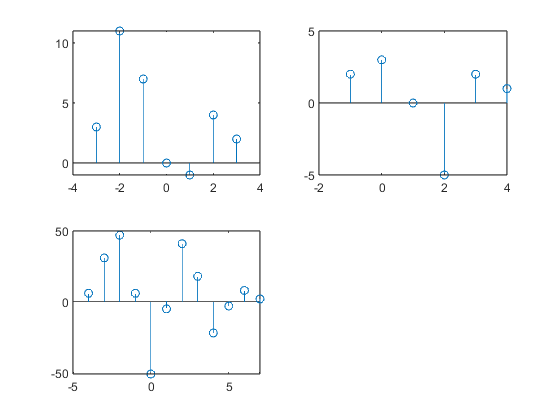

subplot(2,2,3);stem(ny,y);

## ex2.11

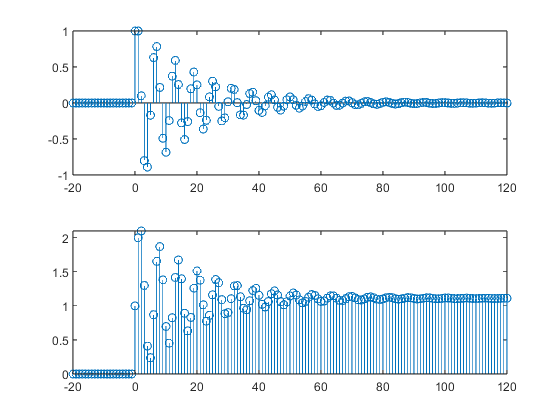

clear;clf;
b=[1];
a=[1,-1,0.9];
n=[-20:120];
h=impz(b,a,n);
subplot(2,1,1);stem(n,h);
x=stepseq(0,-20,120);
s=filter(b,a,x);
subplot(2,1,2);stem(n,s)

## ex2.10

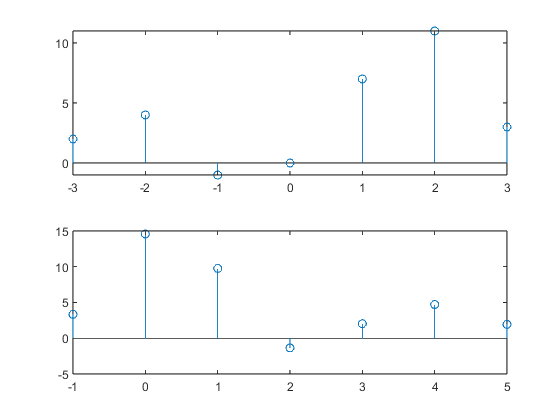

clear;clf;
x=[3,11,7,0,-1,4,2];
nx=[-3:3];
%subplot(2,1,1);
%stem(nx,x);
[y,ny]=sigshift(x,nx,2);
%subplot(2,1,2);
%stem(ny,y);
w=randn(1,length(y));
nw=ny;
[y,ny]=sigadd(y,ny,w,nw);
[x,nx]=sigfold(x,nx);
subplot(2,1,1);
stem(nx,x);
subplot(2,1,2);
stem(ny,y);

## ex3.4.2

Dt = 5e-5; t = -0.005:Dt:0.005; xa = exp(-1000*abs(t));
Wmax = 2*pi*2000; K = 500; k = 0:K; W = k*Wmax/K;
Xa = xa*exp(-j*t'*W)*Dt; Xa = real(Xa);
W = [-fliplr(W),W(2:501)];
Xa = [fliplr(Xa),Xa(2:501)];
subplot(2,1,1); plot(t*1000,xa);
subplot(2,1,2);plot(W/(2*pi*1000),Xa*1000);

## ex3.4.4

Ts=0.0002;Fs=1/Ts;
n=-25:1:25;
nTs=n*Ts;
x=exp(-1000*abs(nTs));
Dt=0.00005;
t=-0.005:Dt:0.005;
xa=x*sinc(Fs*(ones(length(n),1)*t-nTs'*ones(1,length(t))));
error=max(abs(xa-exp(-1000*abs(t))))

error = 0.0363

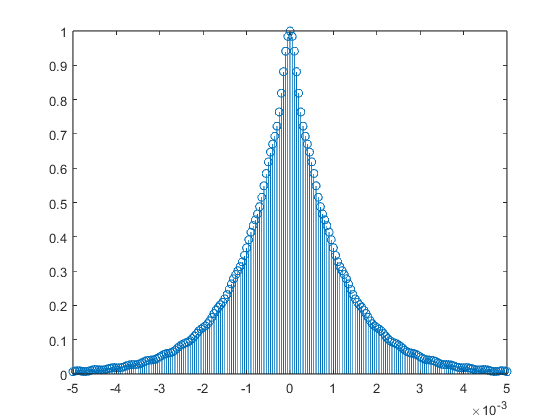

stem(t,xa)

Ts=0.001;Fs=1/Ts;
n=-25:1:25;
nTs=n*Ts;
x=exp(-1000*abs(nTs));
Dt=0.00005;
t=-0.005:Dt:0.005;
xa=x*sinc(Fs*(ones(length(n),1)*t-nTs'*ones(1,length(t))));
error=max(abs(xa-exp(-1000*abs(t))))

error = 0.1852

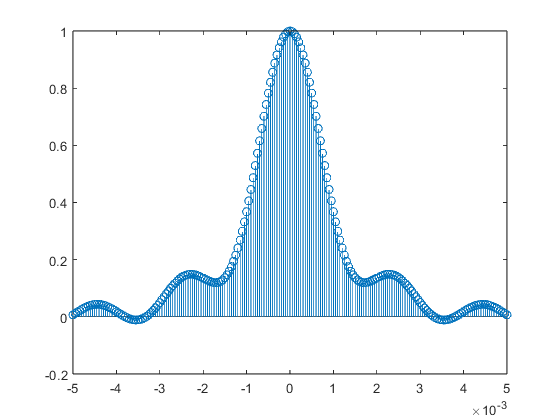

stem(t,xa)

## ex4.8

b=[0,1];a=[3,-4,1];
[R,p,C]=residuez(b,a)

R =     0.5000
   -0.5000


p =     1.0000
    0.3333



C =

     []



## ex4.6

b=[0,0,0,0.25,-0.5,0.0625];
a=[1,-1,0.75,-0.25,0.0625];
[delta,n]=impseq(0,0,7)

delta = 1×8 logical 数组
   1   0   0   0   0   0   0   0


n =      0     1     2     3     4     5     6     7


x=filter(b,a,delta)

x =                    0                   0                   0   0.250000000000000  -0.250000000000000  -0.375000000000000  -0.125000000000000   0.078125000000000


## ex4.11

b=[1,0];a=[1,-0.9];
zplane(b,a)

[H,w]=freqz(b,a,200,'whole')

H =  10.000000000000002 + 0.000000000000000i
  9.225048726532945 - 2.596361717312115i
  7.510092924901202 - 4.170006726662939i
  5.781162499922416 - 4.708433323219140i
  4.426668411928698 - 4.662398360859491i
  3.453889450297605 - 4.377695835271147i
  2.768226163035204 - 4.026535580910988i
  2.280699257200789 - 3.680029022382908i
  1.927491472917517 - 3.363183410481945i
  1.666053853261523 - 3.081966197899619i


w =                    0
   0.031415926535898
   0.062831853071796
   0.094247779607694
   0.125663706143592
   0.157079632679490
   0.188495559215388
   0.219911485751286
   0.251327412287183
   0.282743338823081


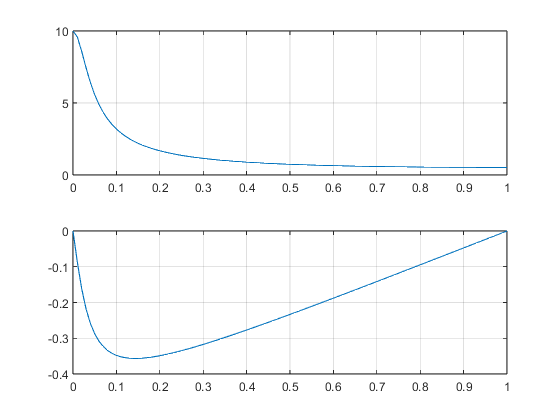

magH=abs(H(1:101));phaH=angle(H(1:101));
subplot(2,1,1);plot(w(1:101)/pi,magH);grid;
subplot(2,1,2);plot(w(1:101)/pi,phaH/pi);grid

## ex4.15

b=[1,1,1]/3;a=[1,-0.95,0.9025];
Y=[-2,-3];X=[1,1];
xic=filtic(b,a,Y,X)

xic =    1.474166666666667   2.138333333333333


## ex5.2

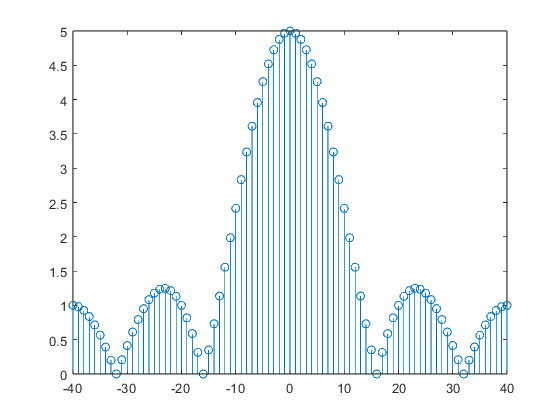

L=5;N=80;k=[-N/2:N/2];
xn=[ones(1,L),zeros(1,N-L)];
Xk=dfs(xn,N);
magXk=abs([Xk(N/2+1:N),Xk(1:N/2+1)]);
figure,stem(k,magXk)

## ex5.5

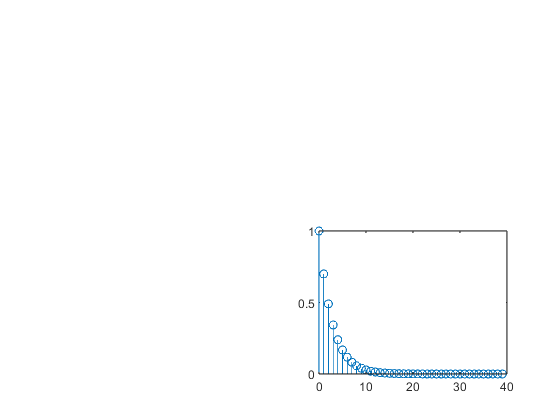

N=40;k=0:N-1;
wk=2*pi*k/N;
zk=exp(j*wk);
Xk=zk./(zk-0.7);
xn=real(idfs(Xk,N));
xtilde=xn'*ones(1,8);
xtilde=(xtilde(:))';
figure,subplot(2,2,4);
stem(0:39,xtilde(1:40));

## ex5.8

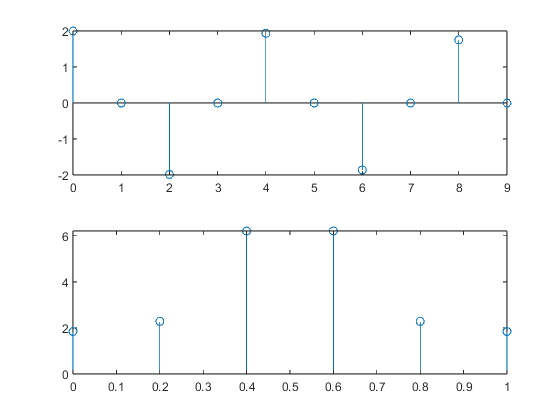

n=[0:99];
x=cos(0.48*pi*n)+cos(0.52*pi*n);
n1=[0:9];y1=x(1:10);
figure;subplot(2,1,1);stem(n1,y1);
Y1=dft(y1,10);
magY1=abs(Y1(1:6));
k1=0:5;w1=2*k1/10;
subplot(2,1,2);stem(w1,magY1);

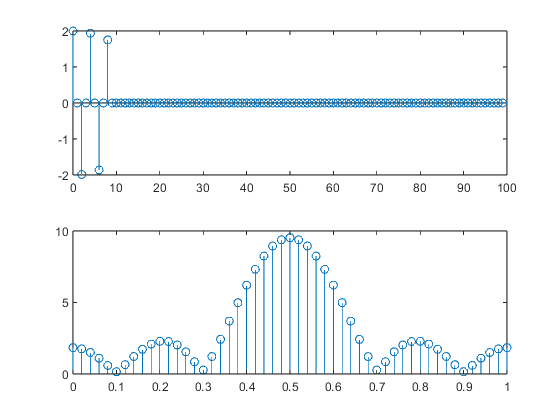


n2=[0:99];y2=[x(1:10),zeros(1,90)];
figure;subplot(2,1,1);stem(n2,y2);
Y2=dft(y2,100);
magY2=abs(Y2(1:51));
k2=0:50;w2=2*k2/100;
subplot(2,1,2);stem(w2,magY2);

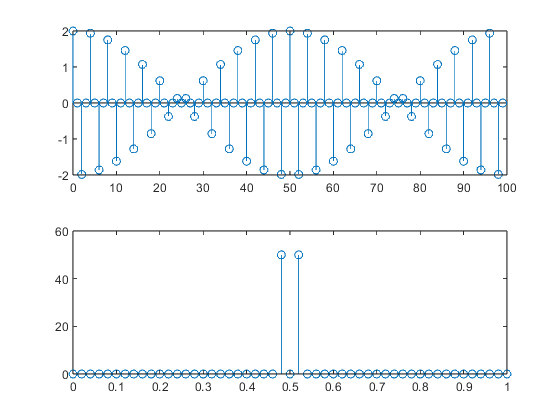


figure;subplot(2,1,1);stem(n,x);
X=dft(x,100);magX=abs(X(1:51));
k=0:50;w=2*k/100;
subplot(2,1,2);stem(w,magX);

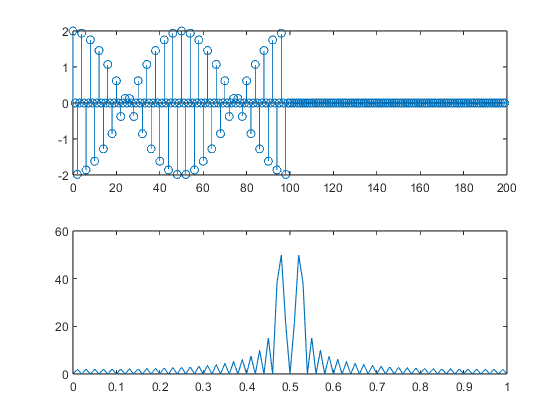


n3=[0:199];y3=[x,zeros(1,100)];
figure;subplot(2,1,1);stem(n3,y3);
Y3=dft(y3,200);
magY3=abs(Y3(1:101));
k3=0:100;w3=2*k3/200;
subplot(2,1,2);plot(w3,magY3);

## ex5.12

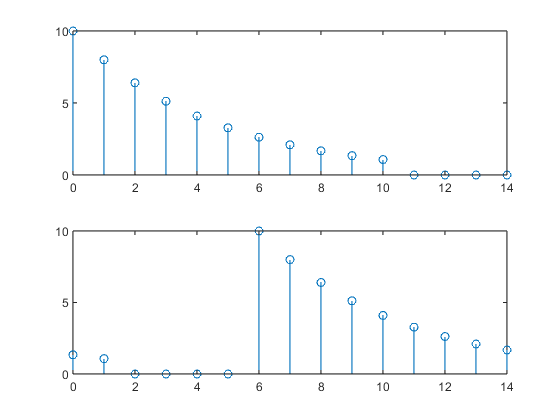

n=0:10;
x=10*0.8.^n;
y=cirshftt(x,6,15);
n=0:14;
x=[x,zeros(1,4)];
figure;
subplot(2,1,1);stem(n,x);
subplot(2,1,2);stem(n,y);

## ex5.22

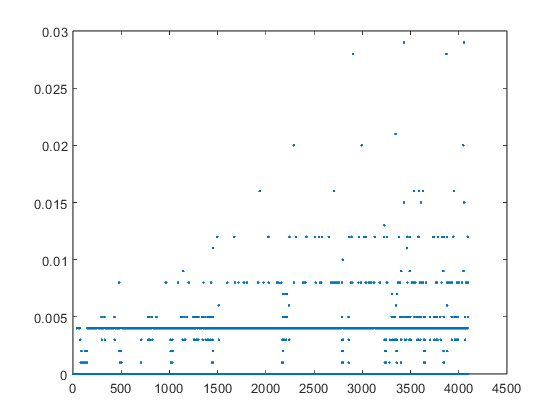

Nmax=4096;
fft_time=zeros(1,Nmax);
for n=1:Nmax
	x=rand(1,n);
	t=clock;
	fft(x);
	fft_time(n)=etime(clock,t);
end
n=[1:Nmax];
plot(n,fft_time,'.')

## ex5.23

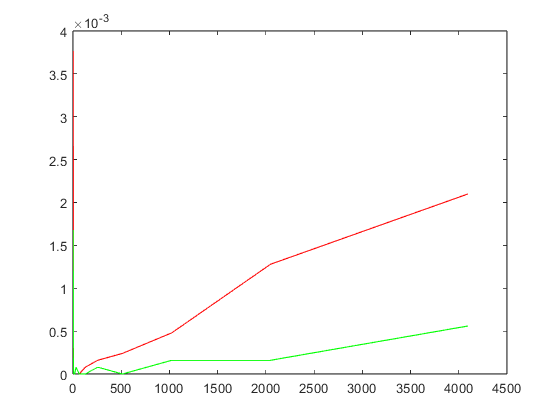

conv_time=zeros(1,12);
fft_time=zeros(1,12);
for nu=1:12
	tc=0;tf=0;
	N=2*2^nu-1;
	N=2^nu;
	for k=1:50
		h=randn(1,N);
		x=rand(1,N);
		t0=clock;
		y1=conv(h,x);
		t1=etime(clock,t0);
		tc=tc+t1;
		t0=clock;
		y2=ifft(fft(h,N).*fft(x,N));
		t2=etime(clock,t0);
		tf=tf+t2;
	end
	conv_time(nu)=tc/50;
	fft_time(nu)=tf/50;
end
n=1:12;n=2.^n;
plot(n,conv_time,'red',n,fft_time,'green')

## P5.41

x=-1+2*rand(1,1e6);
n=0:100;
h=sin(0.4*pi*n);
t0=clock;y1=conv(x,h);tc=etime(clock,t0)

tc = 0.0200

t0=clock;y2=hsolpsav(x,h,2^14);tf=etime(clock,t0)

tf = 0.0800

t0=clock;y3=hsolpadd(x,h,2^14);tf=etime(clock,t0)

tf = 10.4240

## ex7.8

wp=0.2*pi;
ws=0.3*pi;
tr_width=ws-wp;
M=ceil(6.6*pi/tr_width)+1;
n=[0:M-1];
wc=(ws+wp)/2;
hd=ideal_lp(wc,M);
w_ham=(hamming(M))';
h=hd.*w_ham;
[db,mag,pha,grd,w]=freqz_m(h,[1]);
delta_w=2*pi/1000;
Rp=-(min(db(1:wp/delta_w+1)));
As=-round(max(db(ws/delta_w+1:501)));

## ex7.9

wp=0.2*pi;
ws=0.3*pi;
As=50;
tr_width=ws-wp;
M=ceil((As-7.95)/(2.285*tr_width)+1)+1;
n=[0:M-1];
beta=0.1102*(As-8.7);
wc=(ws+wp)/2;
hd=ideal_lp(wc,M);
w_kai=(kaiser(M,beta))';
h=hd.*w_kai;
[db,mag,pha,grd,w]=freqz_m(h,[1]);
delta_w=2*pi/1000;
As=-round(max(db(ws/delta_w+1:501)));

## ex7.10

ws1=0.2*pi;
wp1=0.35*pi;
ws2=0.8*pi;
wp2=0.65*pi;
As=60;
tr_width=min((wp1-ws1),(ws2-wp2));
M=ceil(11*pi/tr_width)+1;
n=[0:M-1];
wc1=(ws1+wp1)/2;
wc2=(wp2+ws2)/2;
dh=ideal_lp(wc,M)-ideal_lp(wc1,M);
w_bla=(blackman(M))';
h=hd.*w_bla;

矩阵维度必须一致。

[db,mag,pha,grd,w]=freqz_m(h,[1]);
delta_w=2*pi/1000;
Rp=-min(db(wp1/delta_w+1:wp2/delta_w));
As=-round(max(db(ws2/delta_w+1:501)));

## ex7.11

M=45;As=60;
n=[0:M-1];
beta=0.1102*(As-8.7);
w_kai=(kaiser(M,beta))';
wc1=pi/3;
wc2=2*pi/3;
hd=ideal_lp(wc1,M)+ideal_lp(pi,M)-ideal_lp(wc2,M);
h=hd.*w_kai;
[db,mag,pha,grd,w]=freqz_m(h,[1]);

M=45;As=60;
n=[0:M-1];
beta=0.1102*(As-8.7)+0.3;
w_kai=(kaiser(M,beta))';
wc1=pi/3;
wc2=2*pi/3;
hd=ideal_lp(wc1,M)+ideal_lp(pi,M)-ideal_lp(wc2,M);
h=hd.*w_kai;
[db,mag,pha,grd,w]=freqz_m(h,[1]);

## ex7.12

M=21;alpha=(M-1)/2;
n=[0:M-1];
hd=(cos(pi*(n-alpha)))./(n-alpha);
hd(alpha+1)=0;
w_ham=(hamming(M))';
h=hd.*w_ham;
[Hr,w,P,L]=Hr_Type3(h);

## ex7.13

M=25;alpha=(M-1)/2;
n=[0:M-1];
hd=2/pi*((sin(pi/2*(n-alpha)).^2)./(n-alpha));
hd(alpha+1)=0;
w_han=(hann(M))';
h=hd.*w_han;
[Hr,w,P,L]=Hr_Type3(h);